### Intersections of Line Segment with Polyshape

In this example, we find the intersections of a reference line segment running from (0,0) to (1,1) with the boundary of a triangular donut, represented as a polyshape object.

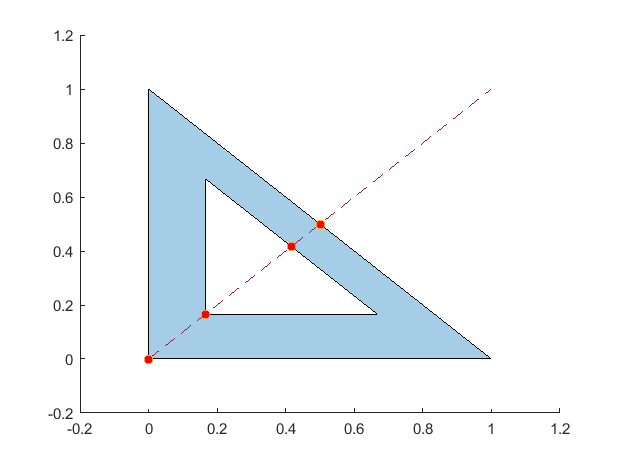


polyOut=polyshape([0 0; 1 0; 0 1]); %Create triangular polyshape with hole
polyIn=polyOut.scale(0.5,[1/3,1/3]);
poly=polyOut.subtract(polyIn);

[x1,y1,x2,y2]=deal(0,0,1,1); %line from (0,0) to (1,1)

out=linexlines2D(poly,[x1,y1],[x2,y2]);


%Visualize
plot(poly)
hold on
col=[0.6400 0.0800 0.1800];
plot([x1,x2],[y1,y2],'--','Color',col);
plot(out(1,:),out(2,:),'o','MarkerFaceColor','r');
hold off

ax=axis;

### Intersections of Infinite Line with Polyshape

Continuing the last example, we now find the intersection points between the polyshape and an infinite line satisfying the equation $x+\frac{y}{3}-\frac{1}{2}=0$.

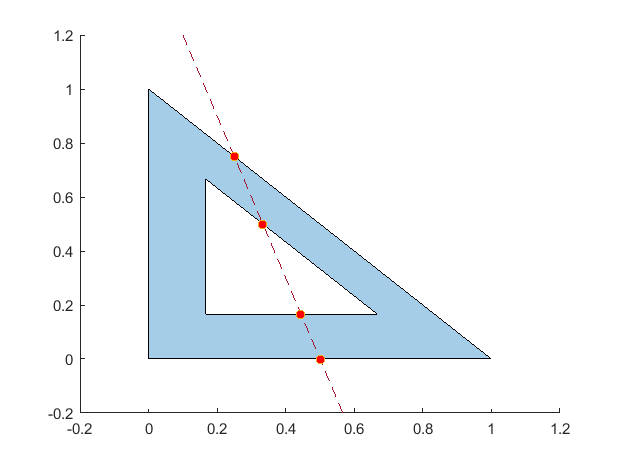


out=linexlines2D(poly,[1,1/3,-1/2]);


%Visualize
plot(poly) 
axis(ax);
hold on
 fimplicit(@(x,y) x+y/3-1/2,'--','Color',col);
 plot(out(1,:),out(2,:),'o','MarkerFaceColor','r');
hold off

### Intersections with a Batch of Line Segments

We consider again the case of a reference line segment running from (0,0) to (1,1), but now we find its intersection with a batch of arbitrary line segments.

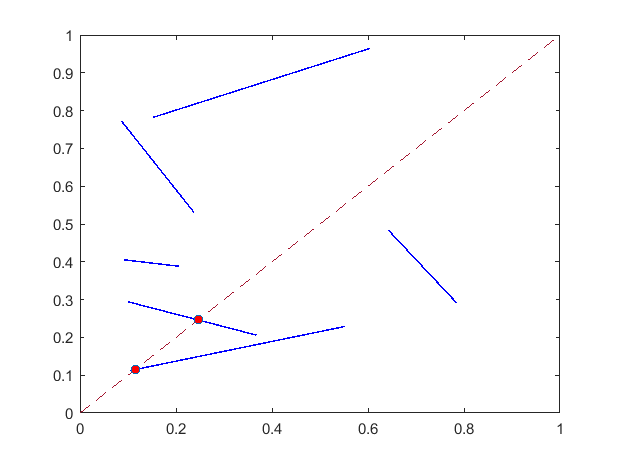

XY1=rand(2,6); XY2=rand(2,6); %random batch of line segment tips

[x1,y1,x2,y2]=deal(0,0,1,1); %reference line segment from (0,0) to (1,1)

out=linexlines2D(XY1,XY2,[x1,y1],[x2,y2]);

%Visualize
figure
for i=1:size(XY1,2)
    plot([XY1(1,i),XY2(1,i)]  , [XY1(2,i),XY2(2,i)],'b','LineWidth',1); hold on
end
plot([x1,x2],[y1,y2],'--','Color',col);
plot(out(1,:),out(2,:),'o','MarkerFaceColor','r');
hold off

ax=axis;

As with earlier examples, The same sort of thing works when the reference line is given by an equation vector:

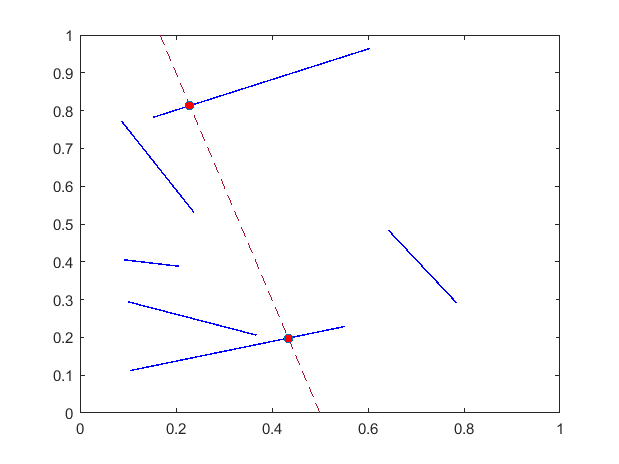


out=linexlines2D(XY1,XY2,[1,1/3,-1/2]);


%Visualize
figure
for i=1:size(XY1,2)
    plot([XY1(1,i),XY2(1,i)]  , [XY1(2,i),XY2(2,i)],'b','LineWidth',1); hold on
end
 axis(ax);
 fimplicit(@(x,y) x+y/3-1/2,'--','Color',col);
 plot(out(1,:),out(2,:),'o','MarkerFaceColor','r');
hold off

### Intersections with a Batch of Infinite Lines

In this example, we take the batch of line segments from the previous example and extend them to infinity. The equations for each infinite line can be obtained as

w=ones(1,size(XY1,2));
E=cross( [XY1;w],  [XY2;w]);

Here `E` is a 3xN matrix such that `E(:,i)` is the equation vector of the i-th line.We now repeat the computations from the previous example. First, the intersections with the reference line segment from  (0,0) to (1,1) is given by,

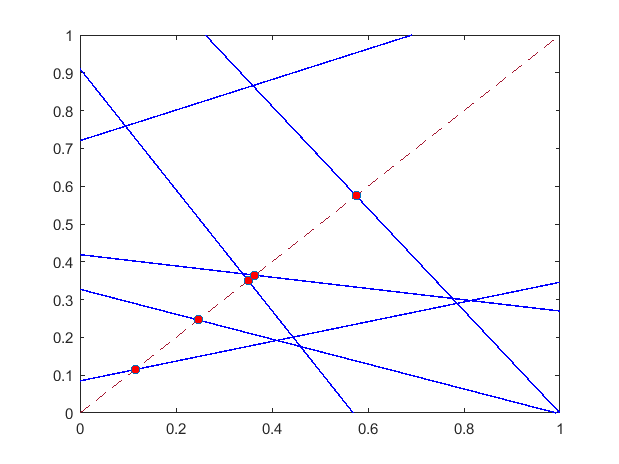

[x1,y1,x2,y2]=deal(0,0,1,1); %reference line segment from (0,0) to (1,1)

out=linexlines2D(E,[x1,y1],[x2,y2]);

%Visualize
figure
for i=1:size(XY1,2)
    fn=@(x,y) reshape( [x(:),y(:),x(:).^0]*E(:,i)   , size(x));
    warning off; fimplicit(fn,'b','LineWidth',1); warning on; hold on
end
plot([x1,x2],[y1,y2],'--','Color',col);
plot(out(1,:),out(2,:),'o','MarkerFaceColor','r');
hold off
axis(ax)

Likewise, we can compute the intersections of the batch with the infinite reference line satisfying the equation $x+\frac{y}{3}-\frac{1}{2}=0$.

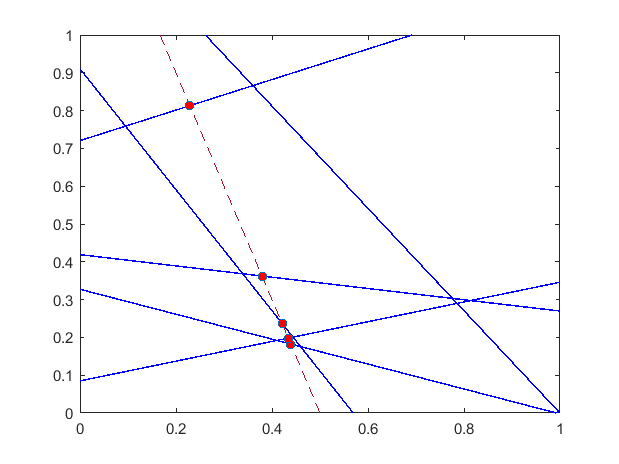


out=linexlines2D(E,[1,1/3,-1/2]);


%Visualize
figure
for i=1:size(XY1,2)
    fn=@(x,y) reshape( [x(:),y(:),x(:).^0]*E(:,i)   , size(x));
    warning off; fimplicit(fn,'b','LineWidth',1); warning on; hold on
end
 axis(ax);
 fimplicit(@(x,y) x+y/3-1/2,'--','Color',col);
 plot(out(1,:),out(2,:),'o','MarkerFaceColor','r');
hold off

Note that because the line segments have been extended to infinity, the results in this section include the same intersections as in the previous section, plus some additional intersections. 